# Ch2: L1 parameter estimates, individual activity

Question 1

clear
t = [3.4935;4.2853;5.1374;5.8181;6.8632;8.1841];
x = [6;10.1333;14.2667;18.4;22.5333;26.6667];

% organize G

G = [ones(6,1),x];

% L1 estimate
s_l1 = irls(G, t, 1e-3, 1e-3, 1, 20)

s_l1 =     2.1786
    0.2079


t_pred = G*s_l1;


% least square estimate s2
s2 = inv(G'*G)*G'*t;

t_pred2 = G*s2;


% plot the data and the fitted model, and the residuals.

figure(1)

plot(x,t,'o','MarkerSize',8)
hold on 
errorbar(x,t_pred,0.1*ones(size(t_pred)),'LineWidth',1.2)
hold on
errorbar(x,t_pred2,0.1*ones(size(t_pred)),'LineWidth',1.2)
xlabel('Distance (m)')
legend('Observed','Predicted from L1','Predicted from L2')
ylabel('Time (s)')
xlim([5,30])
set(gca,'fontsize',14)
title('Data')

Question 2

q = 5000;

for i =1:q
    M (:,i)= irls(G, t_pred + 0.1*randn(size(t_pred)), 1e-3, 1e-3, 1, 50);
end

std(t_pred2-t)

ans = 0.1937

**qq plot**

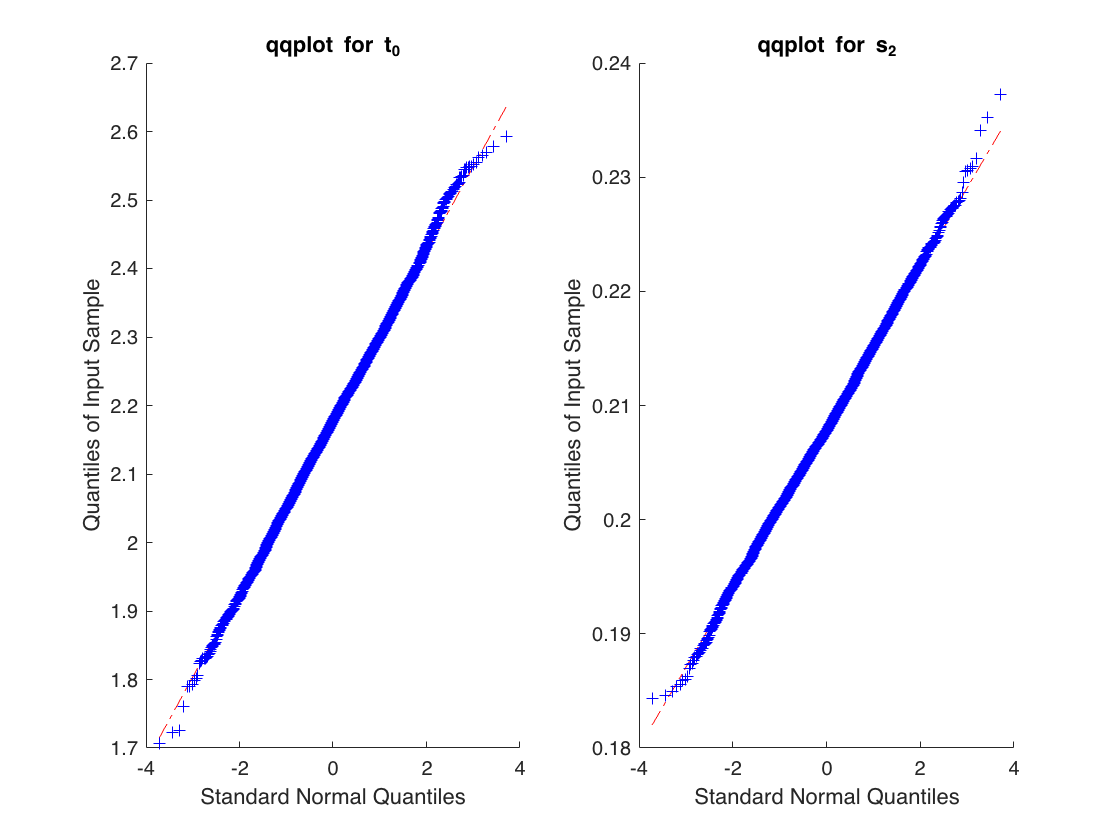

figure
subplot(1,2,1)
qqplot(M(1,:))
title('qqplot for t_0')
subplot(1,2,2)
qqplot(M(2,:))
title('qqplot for s_2')

Question 3

(a)

t0sort = sort(abs(s_l1(1)-M(1,:)));
t0_in = t0sort(q*0.95)

t0_in = 0.2506

s2sort = sort(abs(s_l1(2)-M(2,:)));
s2_in = s2sort(q*0.95)

s2_in = 0.0138

(b)

A = M - s_l1;
cov = A*A'/q

cov =     0.0160   -0.0008
   -0.0008    0.0000


1.96*sqrt(diag(cov))

ans =     0.2477
    0.0138


CI = [s_l1-1.96*sqrt(diag(cov)), s_l1 + 1.96*sqrt(diag(cov))]

CI =     1.9309    2.4264
    0.1941    0.2217
